%Loading grfs from appendix in winter book
winter_grfs_appendix = readtable('Winter_Appendix_data.xlsx','Sheet',5, 'HeaderLines', 4);

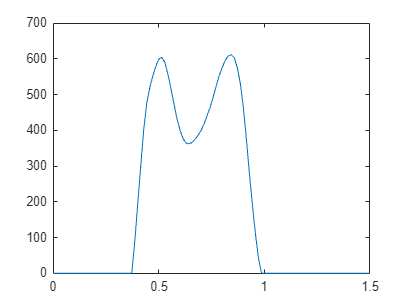


t = winter_grfs_appendix.(3).';
winter_grfs = winter_grfs_appendix.(5).';

plot(t,winter_grfs);


save('kinematic_data\winterGRFS.mat', 't', 'winter_grfs');

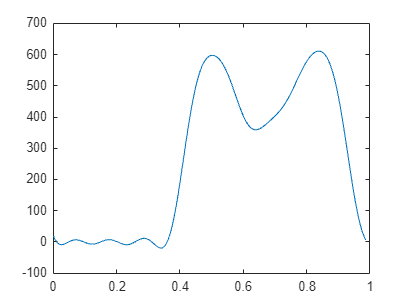

trial_end = 69; %End of 1st complete gait cycle r_leg
t = t(1:trial_end);
t_0 = t(1);
t_f = t(trial_end); %for swing only 27
dt = t(2)-t(1);

winter_grfs = winter_grfs(:,1:trial_end);

int_n = 500;
t1 = linspace(t(1),t(end),int_n); dt = t1(2)-t1(1);

winter_grfs = interp1(t,winter_grfs,t1);

winter_grfs = fit(t1',winter_grfs','fourier8');

winter_grfs = feval(winter_grfs,t1);

plot(t1,winter_grfs);